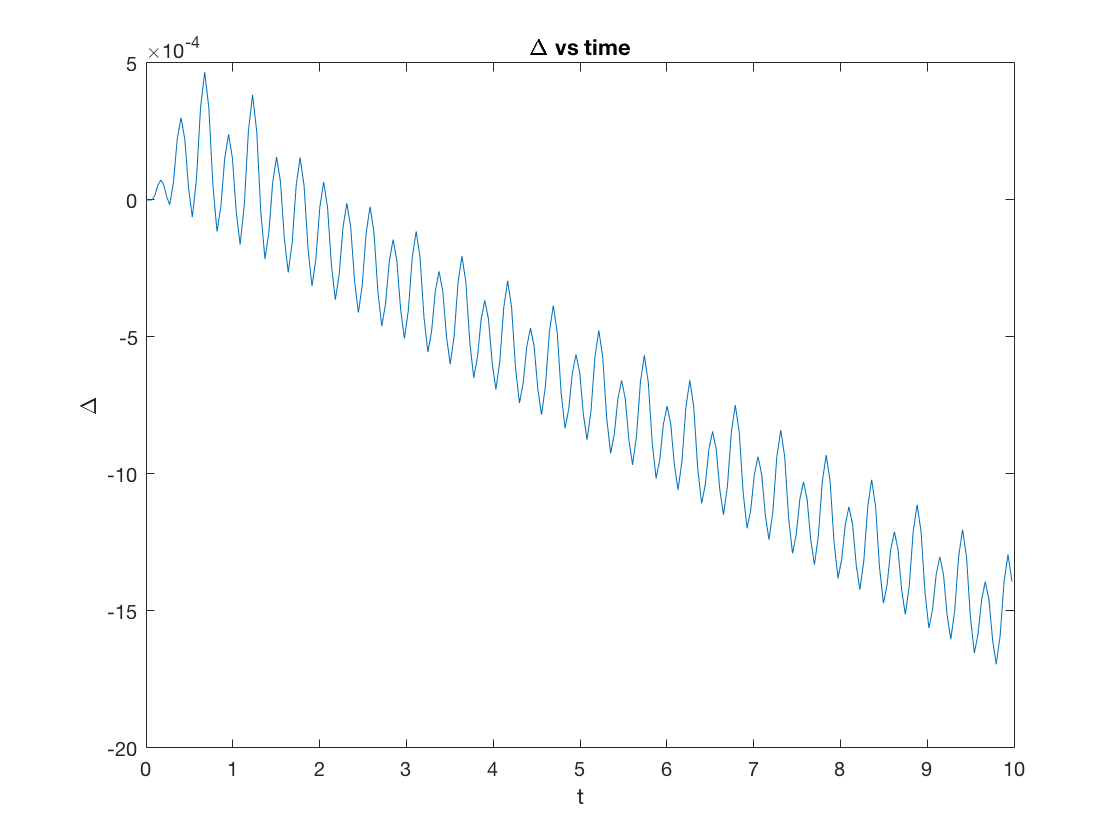

% a)calculate: 
%relative change in the total energy during one cycle and is the function
%"delta" uniformly small during the cycle? choose theta0 = 0.25 and its
%derivative = 0 and omega0^2=9

% b) plot position vs velocity as function of t

% c) compute the average value of KE & PE during 1 cycle
%totalE is conserved



%(omega0,theta0,thetad0,grph)
[period,sol,kenergy,penergy,totenergy]=Pendulum_shm(3,0.25,0);
t=sol(:,1); %entire 1st coloumn
x=sol(:,2);
v=sol(:,3);
delta_n = (totenergy(:)- totenergy(1)) / totenergy(1); %Total energy E(:) reshapes all elements of E into a single column vector. 



figure
plot(t,delta_n); 
title('\Delta vs time');
xlabel('t');
ylabel('\Delta');

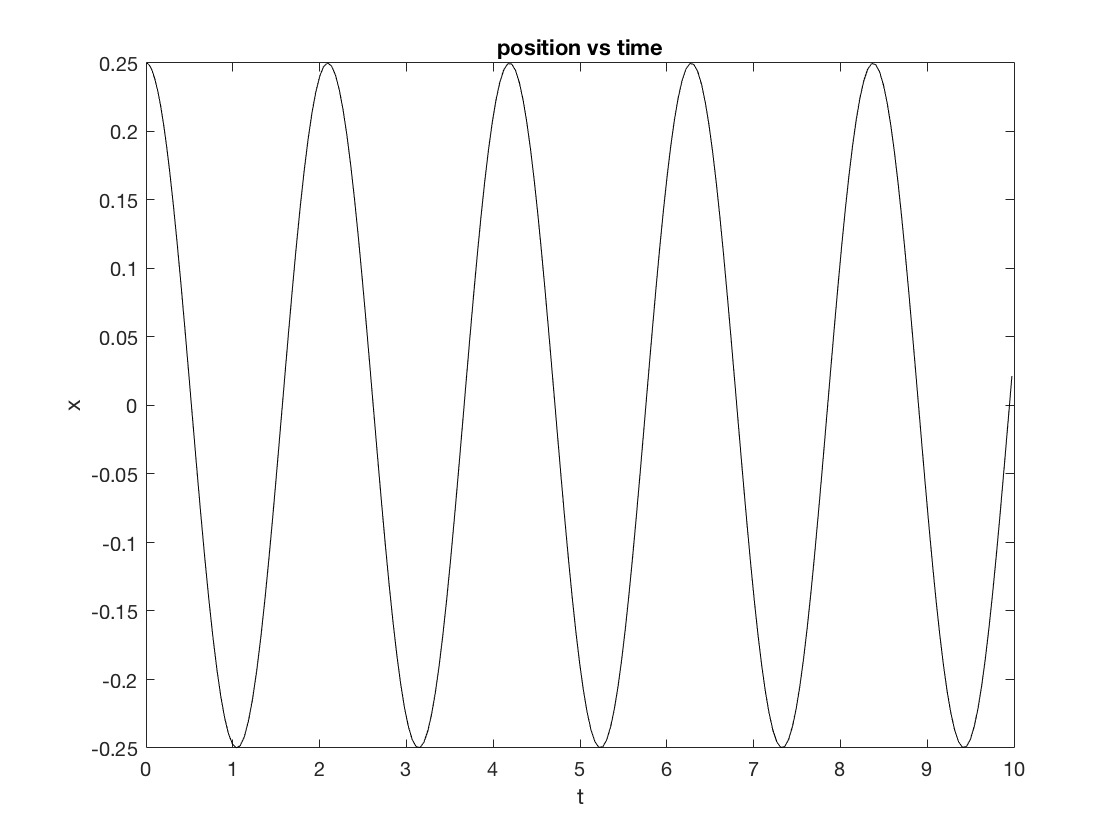

figure
plot(t,x,'k');
title('position vs time'); %position as func of time
xlabel('t');
ylabel('x');

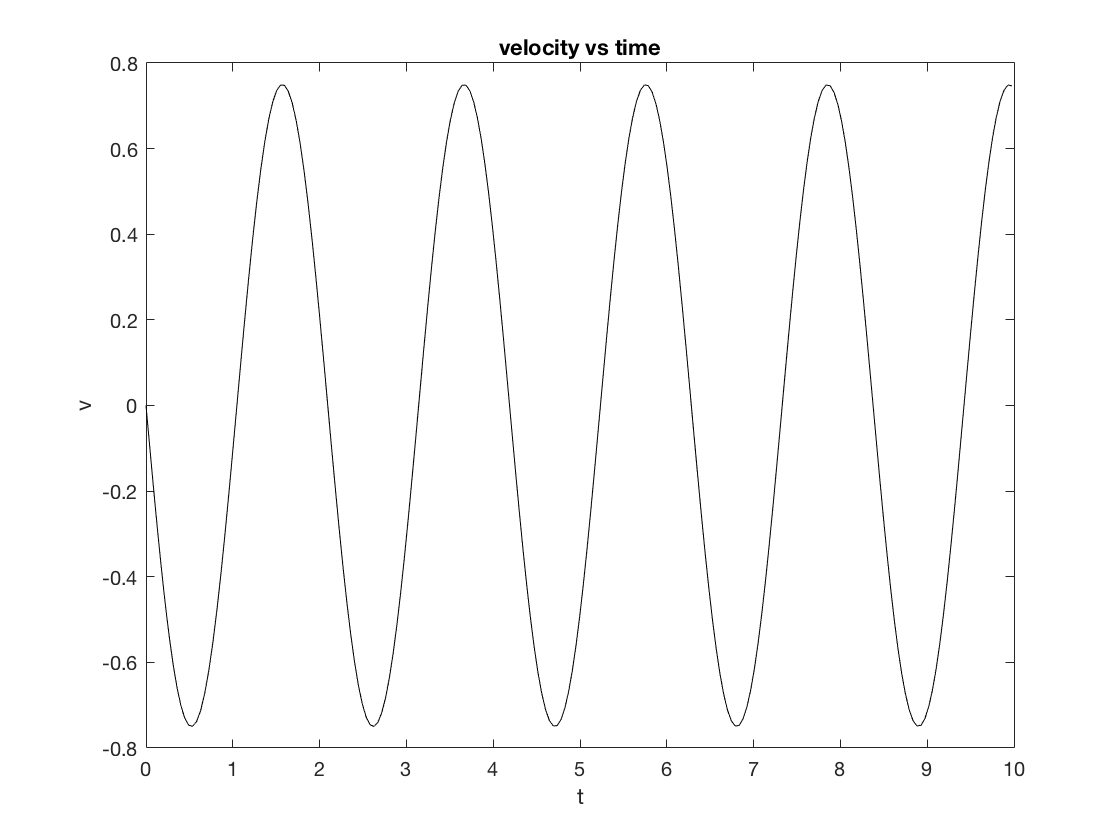

figure
plot(t,v,'k'); 
title('velocity vs time') %velocity as func of time
xlabel('t');
ylabel('v');

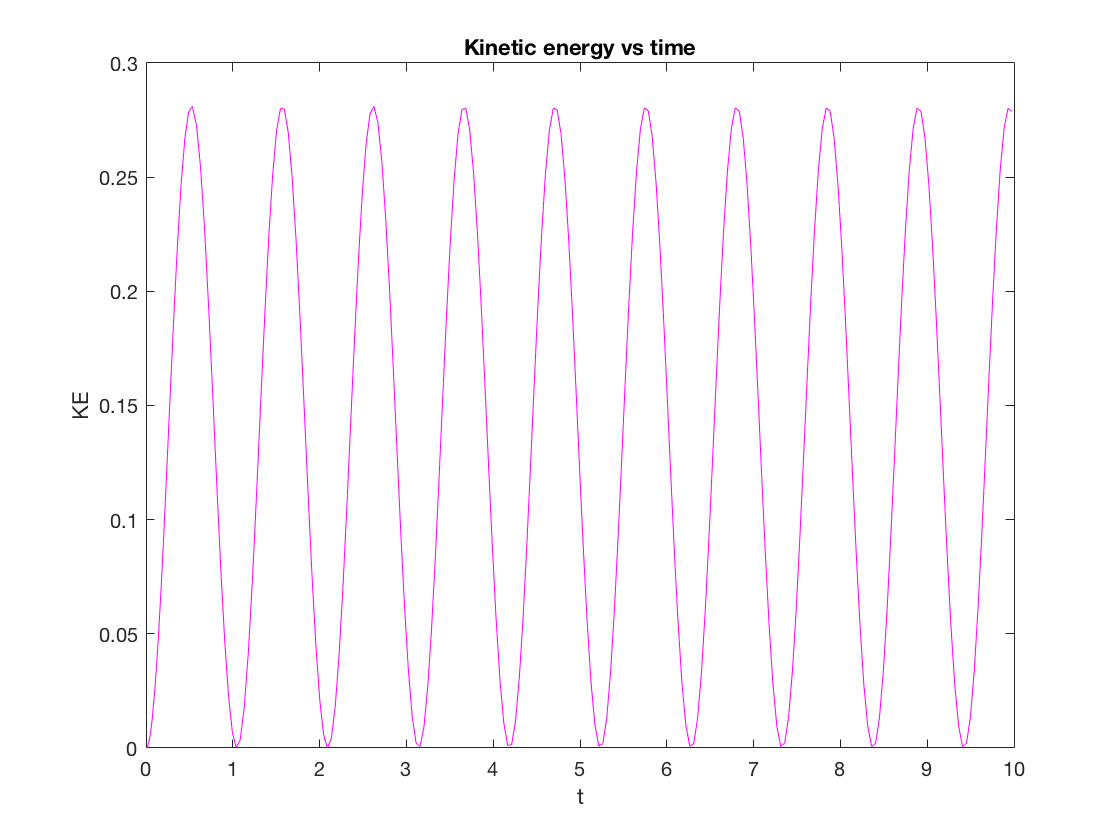

figure
plot(t,kenergy,'m');
title('Kinetic energy vs time');
xlabel('Time');
ylabel('KE');

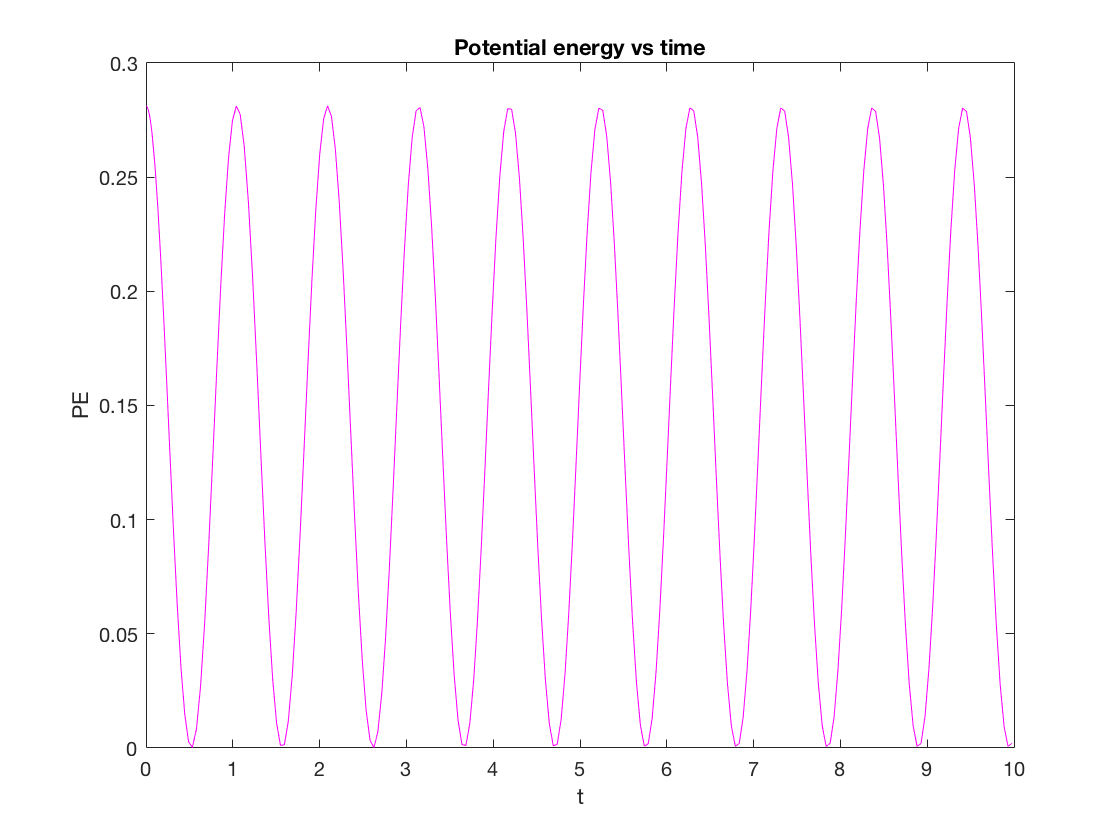

figure
plot(t,penergy,'m');
title('Potential energy vs time');
xlabel('t');
ylabel('PE');

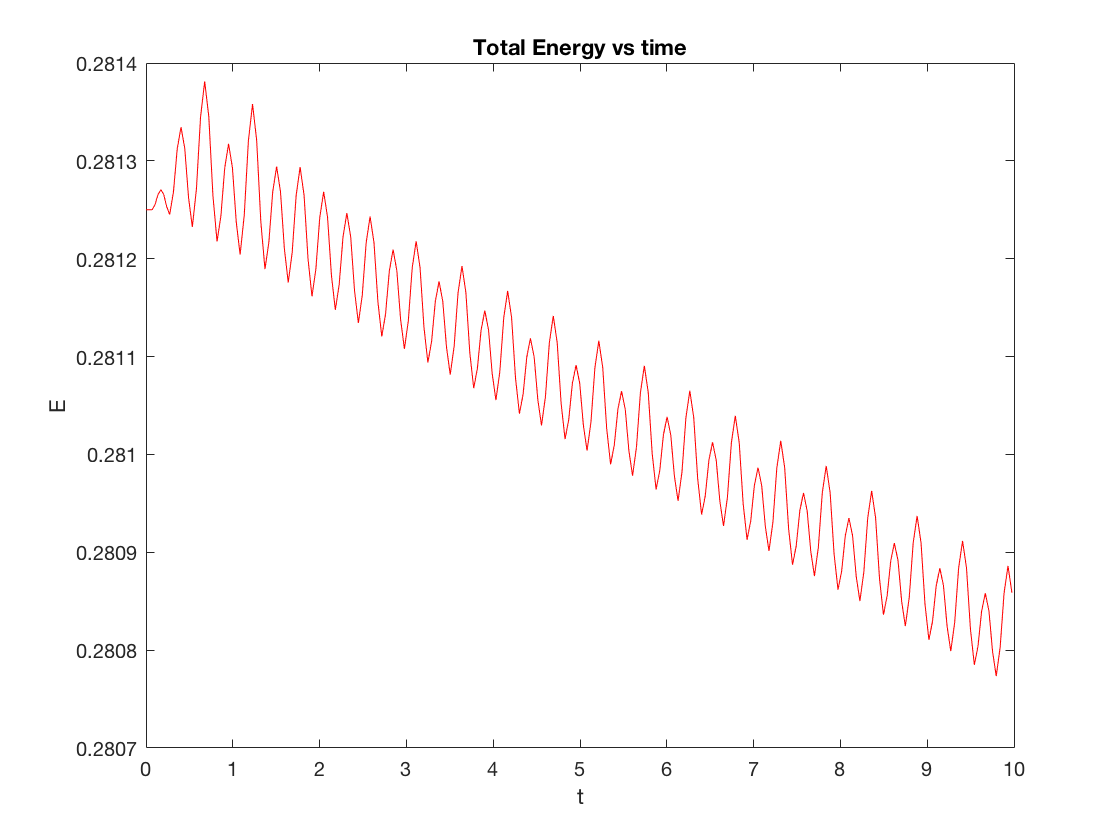

figure
plot(t,totenergy,'r');
title('Total Energy vs time');
xlabel('t');
ylabel('E');

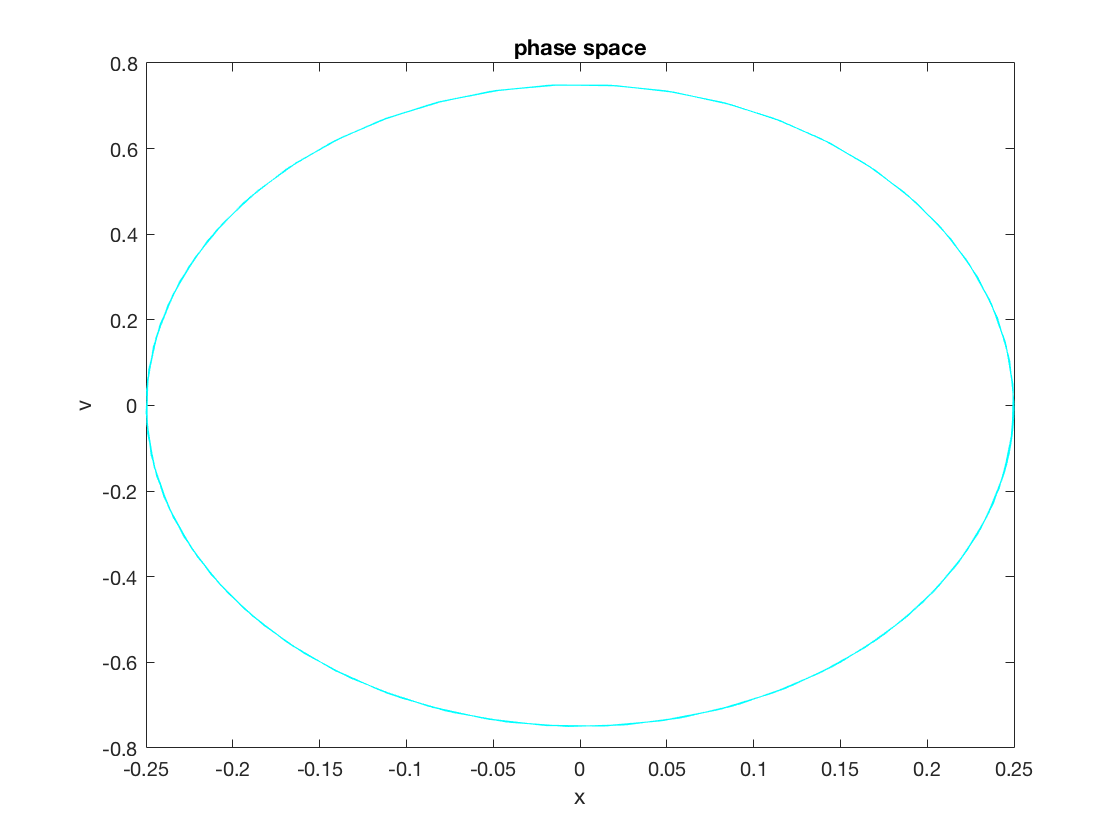


% total energy is constant in time.

figure
plot(x,v,'c');
title('phase space');
xlabel('x');
ylabel('v');

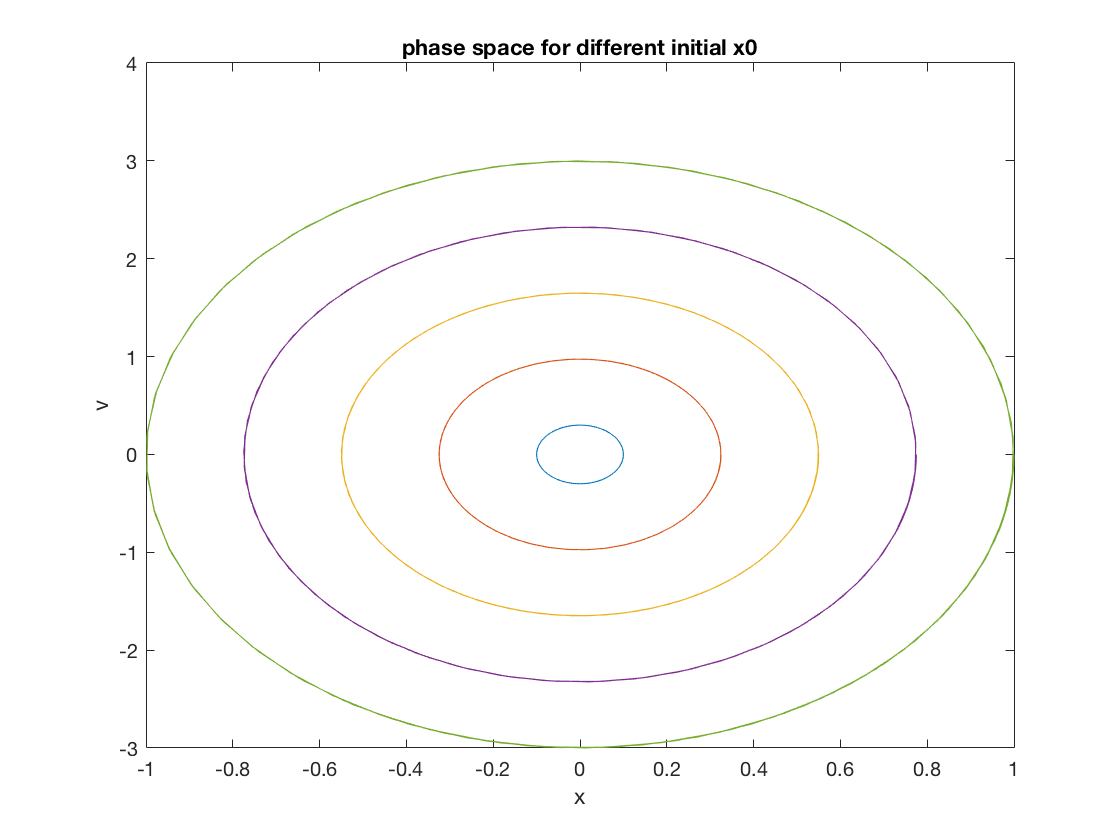

% d) plot path of oscillator in phase space (theta,theta0)
%us different initial conditions with omega0 = 3
%one of the initial condition defines the amplitude and the other phase


initialx=linspace(0.1,1,5); %for different initial conditions
figure(1)

for i = 1:5
    [period,sol]=Pendulum_shm(3,initialx(i),0);
    plot(sol(:,2),sol(:,3)); %position vs velocity: space phase
    hold on;
end

title('phase space for different initial x');
xlabel('Position');
ylabel('Velocity');

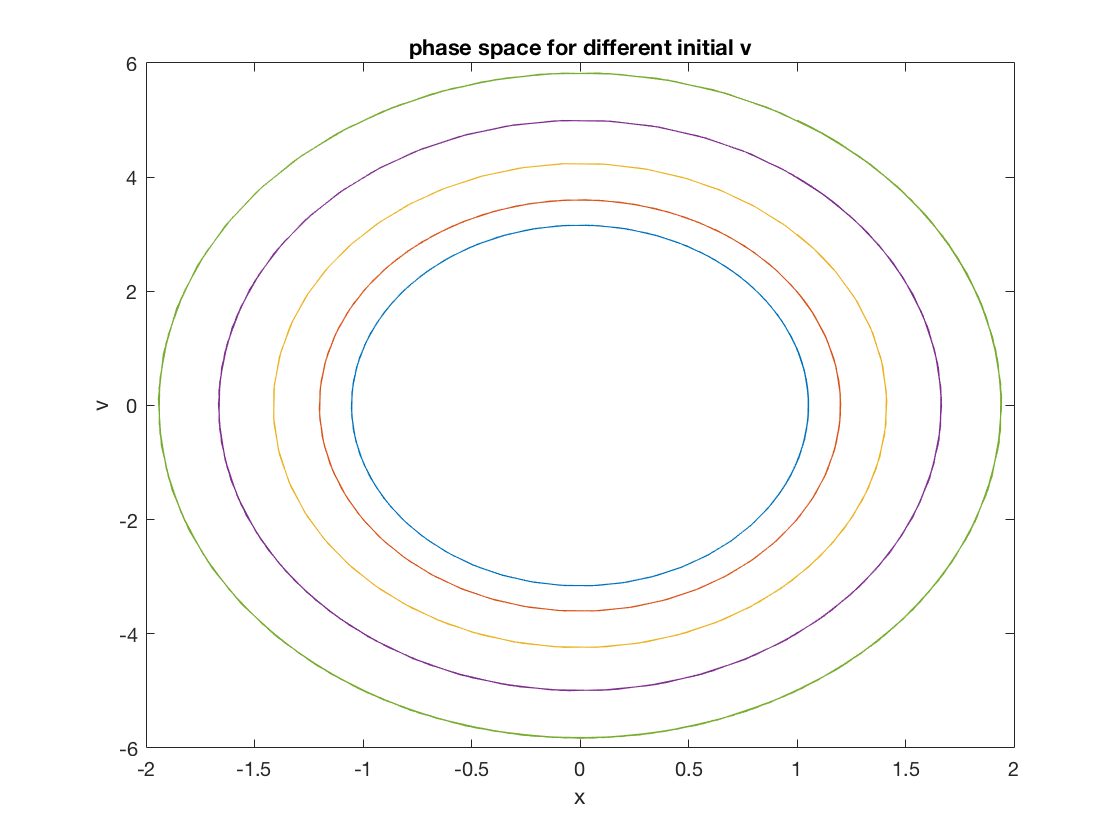



initialv=linspace(1,5,5); %for different initial conditions
figure(2)

for i = 1:5
    [period,sol]=Pendulum_shm(3,1,initialv(i));
    plot(sol(:,2),sol(:,3));
    hold on; %don't use hold all 
end

title('phase space for different initial v');
xlabel('Position');
ylabel('Velocity');


% five different initial conditions each for a different phase space 


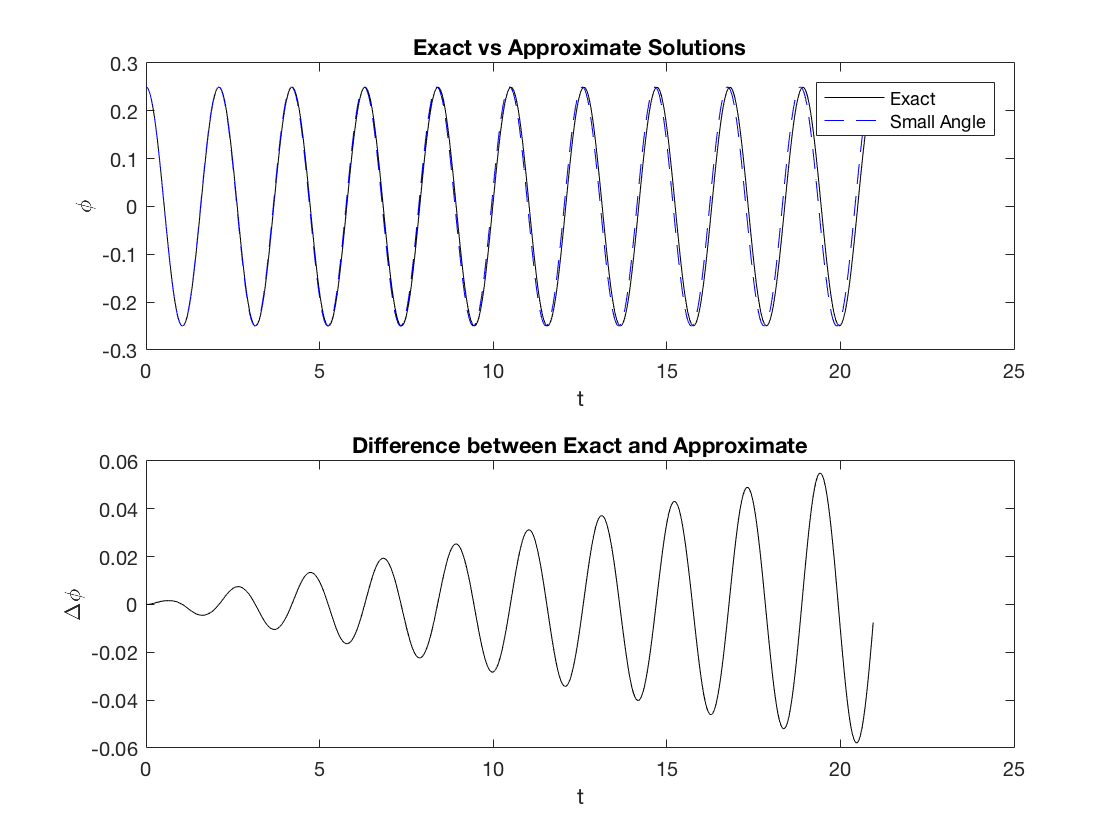

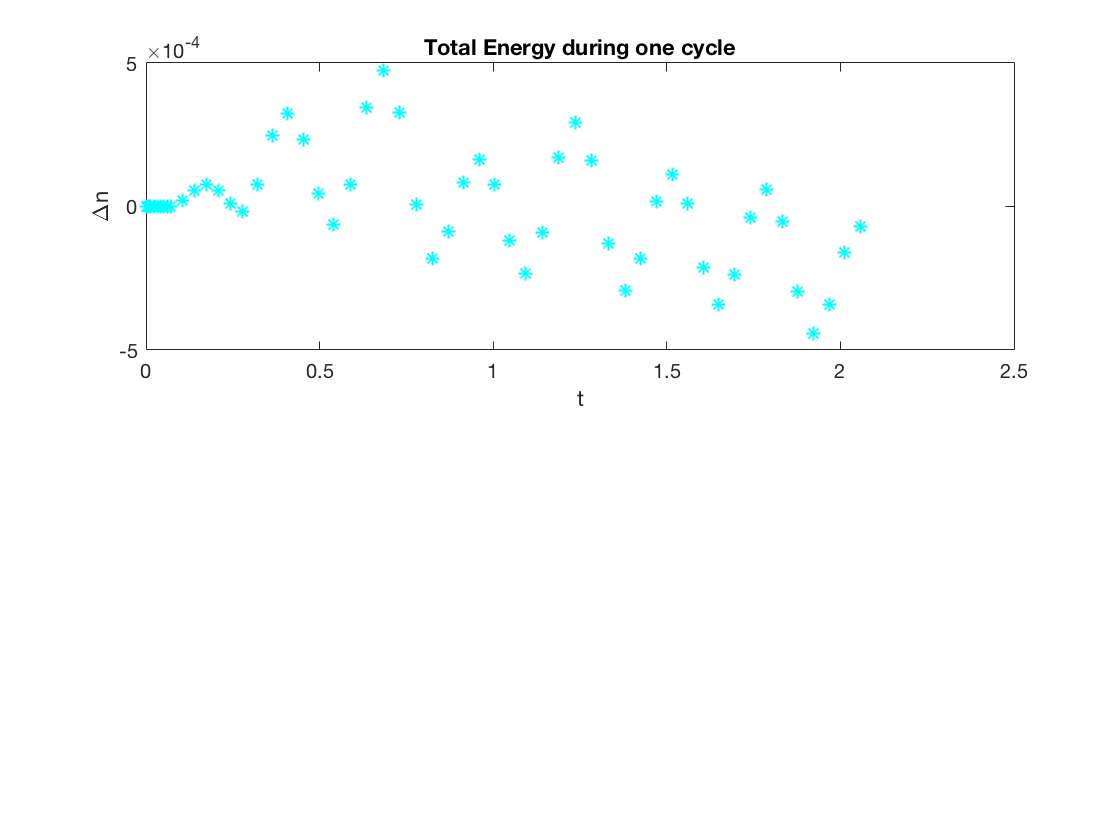

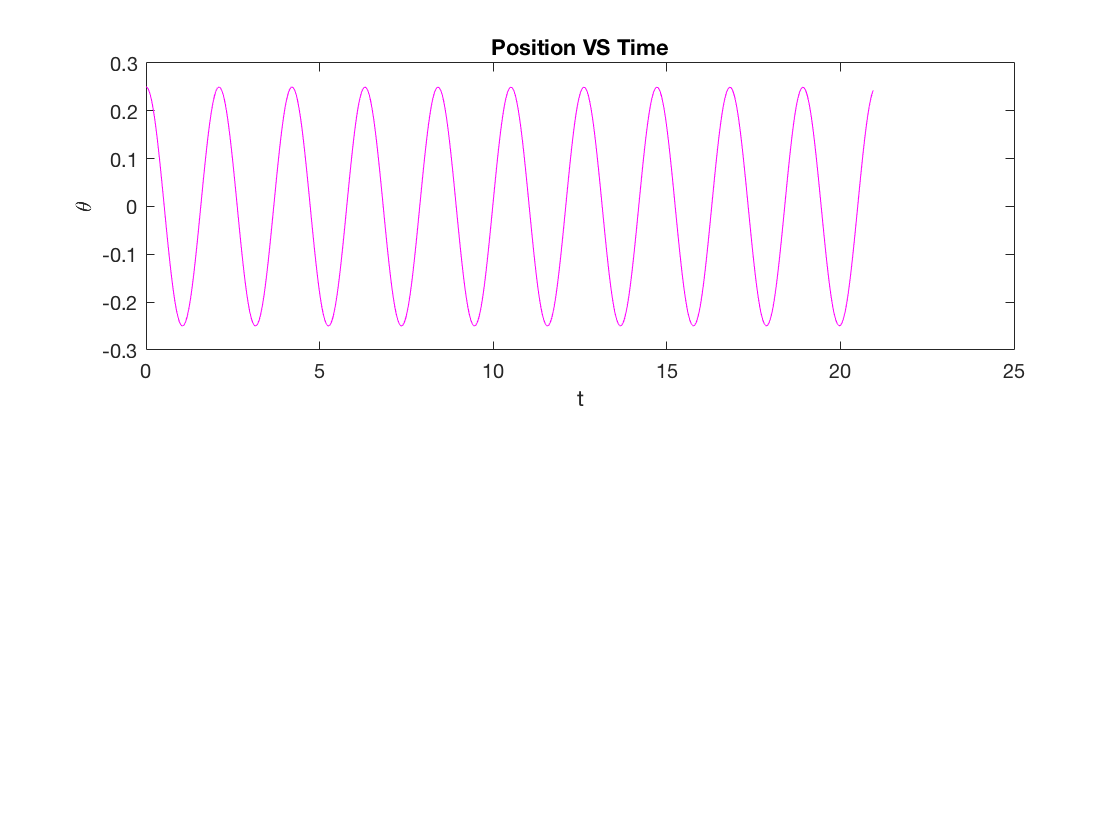

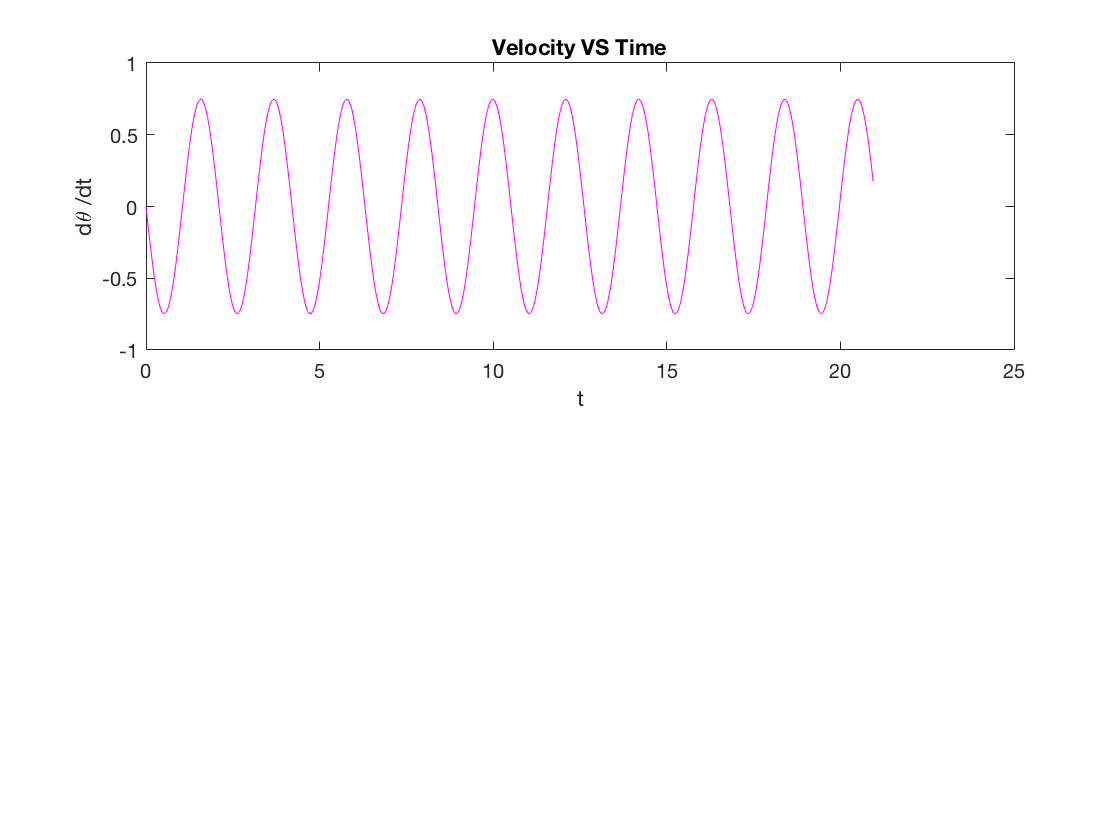

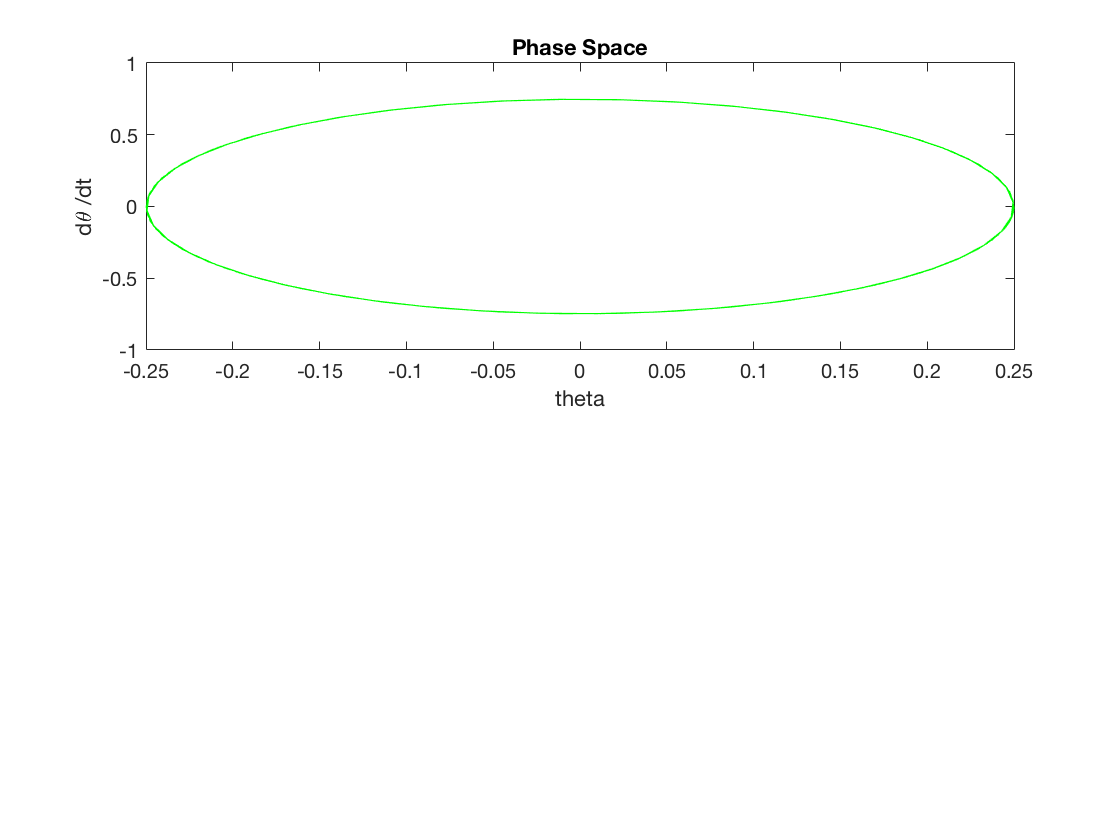

R = 9.81/9;
[period,sol] = Pendulummodified(R,0.25,0);


%check plot of total energy 

